# Derivation of Yaw Only QEKF

syms q0 q1 q2 q3 x real

yaw (q0,q1,q2,q3) = atan2((2 * (q0*q3 + q1*q2)),(1 - 2*(q2^2 + q3^2)))

$$yaw(q0, q1, q2, q3) = \text{atan2}\left(2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2},-2\,{q_{2}}^{2}-2\,{q_{3}}^{2}+1\right)$$


H = [jacobian(cos(yaw/2), [q0,q1,q2,q3]);
     0,0,0,0;
     0,0,0,0;
     jacobian(sin(yaw/2), [q0,q1,q2,q3])]

$$H(q0, q1, q2, q3) = \begin{array}{l} \left(\begin{array}{cccc} \frac{q_{3}\,\sin\left(\sigma_{2}\right)\,\sigma_{5}}{\sigma_{1}} & \frac{q_{2}\,\sin\left(\sigma_{2}\right)\,\sigma_{5}}{\sigma_{1}} & \frac{\sin\left(\sigma_{2}\right)\,\sigma_{3}\,{\sigma_{5}}^{2}}{2\,\sigma_{1}} & \frac{\sin\left(\sigma_{2}\right)\,\sigma_{4}\,{\sigma_{5}}^{2}}{2\,\sigma_{1}}\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ -\frac{q_{3}\,\cos\left(\sigma_{2}\right)\,\sigma_{5}}{\sigma_{1}} & -\frac{q_{2}\,\cos\left(\sigma_{2}\right)\,\sigma_{5}}{\sigma_{1}} & -\frac{\cos\left(\sigma_{2}\right)\,\sigma_{3}\,{\sigma_{5}}^{2}}{2\,\sigma_{1}} & -\frac{\cos\left(\sigma_{2}\right)\,\sigma_{4}\,{\sigma_{5}}^{2}}{2\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sigma_{5}}^{2}+{\sigma_{6}}^{2}\\ \sigma_{2}=\frac{\text{atan2}\left(\sigma_{6},-2\,{q_{2}}^{2}-2\,{q_{3}}^{2}+1\right)}{2}\\ \sigma_{3}=\frac{2\,q_{1}}{\sigma_{5}}-\frac{4\,q_{2}\,\sigma_{6}}{{\sigma_{5}}^{2}}\\ \sigma_{4}=\frac{2\,q_{0}}{\sigma_{5}}-\frac{4\,q_{3}\,\sigma_{6}}{{\sigma_{5}}^{2}}\\ \sigma_{5}=2\,{q_{2}}^{2}+2\,{q_{3}}^{2}-1\\ \sigma_{6}=2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2} \end{array}$$

Measurement Model

H_new = jacobian(yaw,[q0 q1 q2 q3])

$$H\_new(q0, q1, q2, q3) = \begin{array}{l} \left(\begin{array}{cccc} -\frac{2\,q_{3}\,\sigma_{2}}{\sigma_{1}} & -\frac{2\,q_{2}\,\sigma_{2}}{\sigma_{1}} & -\frac{\left(\frac{2\,q_{1}}{\sigma_{2}}-\frac{4\,q_{2}\,\left(2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2}\right)}{{\sigma_{2}}^{2}}\right)\,{\sigma_{2}}^{2}}{\sigma_{1}} & -\frac{\left(\frac{2\,q_{0}}{\sigma_{2}}-\frac{4\,q_{3}\,\left(2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2}\right)}{{\sigma_{2}}^{2}}\right)\,{\sigma_{2}}^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sigma_{2}}^{2}+{\left(2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2}\right)}^{2}\\ \sigma_{2}=2\,{q_{2}}^{2}+2\,{q_{3}}^{2}-1 \end{array}$$


H = [(q3*sin(atan2((2*q0*q3 + 2*q1*q2), - 2*q2^2 - 2*q3^2 + 1)/2)*(2*q2^2 + 2*q3^2 - 1))/((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2), (q2*sin(atan2((2*q0*q3 + 2*q1*q2), - 2*q2^2 - 2*q3^2 + 1)/2)*(2*q2^2 + 2*q3^2 - 1))/((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2), (sin(atan2((2*q0*q3 + 2*q1*q2), - 2*q2^2 - 2*q3^2 + 1)/2)*((2*q1)/(2*q2^2 + 2*q3^2 - 1) - (4*q2*(2*q0*q3 + 2*q1*q2))/(2*q2^2 + 2*q3^2 - 1)^2)*(2*q2^2 + 2*q3^2 - 1)^2)/(2*((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2)), (sin(atan2((2*q0*q3 + 2*q1*q2), - 2*q2^2 - 2*q3^2 + 1)/2)*((2*q0)/(2*q2^2 + 2*q3^2 - 1) - (4*q3*(2*q0*q3 + 2*q1*q2))/(2*q2^2 + 2*q3^2 - 1)^2)*(2*q2^2 + 2*q3^2 - 1)^2)/(2*((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2)); sym(0), sym(0), sym(0), sym(0); sym(0), sym(0), sym(0), sym(0); -(q3*cos(atan2((2*q0*q3 + 2*q1*q2), - 2*q2^2 - 2*q3^2 + 1)/2)*(2*q2^2 + 2*q3^2 - 1))/((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2), -(q2*cos(atan2((2*q0*q3 + 2*q1*q2), - 2*q2^2 - 2*q3^2 + 1)/2)*(2*q2^2 + 2*q3^2 - 1))/((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2), -(cos(atan2((2*q0*q3 + 2*q1*q2), - 2*q2^2 - 2*q3^2 + 1)/2)*((2*q1)/(2*q2^2 + 2*q3^2 - 1) - (4*q2*(2*q0*q3 + 2*q1*q2))/(2*q2^2 + 2*q3^2 - 1)^2)*(2*q2^2 + 2*q3^2 - 1)^2)/(2*((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2)), -(cos(atan2((2*q0*q3 + 2*q1*q2), - 2*q2^2 - 2*q3^2 + 1)/2)*((2*q0)/(2*q2^2 + 2*q3^2 - 1) - (4*q3*(2*q0*q3 + 2*q1*q2))/(2*q2^2 + 2*q3^2 - 1)^2)*(2*q2^2 + 2*q3^2 - 1)^2)/(2*((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2))]

$$H = \begin{array}{l} \left(\begin{array}{cccc} \frac{q_{3}\,\sin\left(\sigma_{3}\right)\,\sigma_{6}}{\sigma_{2}} & \frac{q_{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{6}}{\sigma_{2}} & \frac{\sin\left(\sigma_{3}\right)\,\sigma_{4}\,{\sigma_{6}}^{2}}{\sigma_{1}} & \frac{\sin\left(\sigma_{3}\right)\,\sigma_{5}\,{\sigma_{6}}^{2}}{\sigma_{1}}\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ -\frac{q_{3}\,\cos\left(\sigma_{3}\right)\,\sigma_{6}}{\sigma_{2}} & -\frac{q_{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{6}}{\sigma_{2}} & -\frac{\cos\left(\sigma_{3}\right)\,\sigma_{4}\,{\sigma_{6}}^{2}}{\sigma_{1}} & -\frac{\cos\left(\sigma_{3}\right)\,\sigma_{5}\,{\sigma_{6}}^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\sigma_{6}}^{2}+2\,{\sigma_{7}}^{2}\\ \sigma_{2}={\sigma_{6}}^{2}+{\sigma_{7}}^{2}\\ \sigma_{3}=\frac{\text{atan2}\left(\sigma_{7},-2\,{q_{2}}^{2}-2\,{q_{3}}^{2}+1\right)}{2}\\ \sigma_{4}=\frac{2\,q_{1}}{\sigma_{6}}-\frac{4\,q_{2}\,\sigma_{7}}{{\sigma_{6}}^{2}}\\ \sigma_{5}=\frac{2\,q_{0}}{\sigma_{6}}-\frac{4\,q_{3}\,\sigma_{7}}{{\sigma_{6}}^{2}}\\ \sigma_{6}=2\,{q_{2}}^{2}+2\,{q_{3}}^{2}-1\\ \sigma_{7}=2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2} \end{array}$$


simplify(H_new)

$$ans(q0, q1, q2, q3) = \begin{array}{l} \left(\begin{array}{cccc} -\frac{2\,q_{3}\,\sigma_{2}}{\sigma_{1}} & -\frac{2\,q_{2}\,\sigma_{2}}{\sigma_{1}} & -\frac{\left(\frac{2\,q_{1}}{\sigma_{2}}-\frac{4\,q_{2}\,\left(2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2}\right)}{{\sigma_{2}}^{2}}\right)\,{\sigma_{2}}^{2}}{\sigma_{1}} & -\frac{\left(\frac{2\,q_{0}}{\sigma_{2}}-\frac{4\,q_{3}\,\left(2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2}\right)}{{\sigma_{2}}^{2}}\right)\,{\sigma_{2}}^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sigma_{2}}^{2}+{\left(2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2}\right)}^{2}\\ \sigma_{2}=2\,{q_{2}}^{2}+2\,{q_{3}}^{2}-1 \end{array}$$

Fixing it!

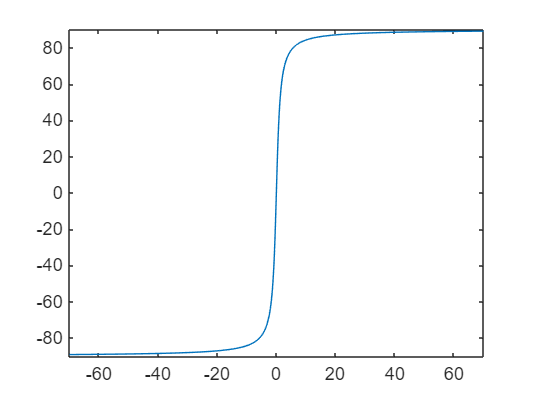

fplot(rad2deg(atan(x)),[-70 70])

syms ya
y = 1.7*pi

y = 5.3407

q = [cos(y/2),0,0,sin(y/2)]

q =    -0.8910         0         0    0.4540


vpa(yaw(cos(y/2),0,0,sin(y/2)))

$$ans = -0.94247779607693810395290442328078$$

yaw_fix (q0,q3) = atan2((2 * (q0*q3)),(1 - 2*(q3^2)))

$$yaw\_fix(q0, q3) = \text{atan2}\left(2\,q_{0}\,q_{3},1-2\,{q_{3}}^{2}\right)$$

fsurf(rad2deg(yaw_fix), [-1 1 -1 1])
xlabel('q0');
ylabel('q3');
zlabel('Yaw');
[-(2*q3*(2*q2^2 + 2*q3^2 - 1))/((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2), -(2*q2*(2*q2^2 + 2*q3^2 - 1))/((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2), -(((2*q1)/(2*q2^2 + 2*q3^2 - 1) - (4*q2*(2*q0*q3 + 2*q1*q2))/(2*q2^2 + 2*q3^2 - 1)^2)*(2*q2^2 + 2*q3^2 - 1)^2)/((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2), -(((2*q0)/(2*q2^2 + 2*q3^2 - 1) - (4*q3*(2*q0*q3 + 2*q1*q2))/(2*q2^2 + 2*q3^2 - 1)^2)*(2*q2^2 + 2*q3^2 - 1)^2)/((2*q2^2 + 2*q3^2 - 1)^2 + (2*q0*q3 + 2*q1*q2)^2)]

$$ans = \begin{array}{l} \left(\begin{array}{cccc} -\frac{2\,q_{3}\,\sigma_{2}}{\sigma_{1}} & -\frac{2\,q_{2}\,\sigma_{2}}{\sigma_{1}} & -\frac{\left(\frac{2\,q_{1}}{\sigma_{2}}-\frac{4\,q_{2}\,\left(2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2}\right)}{{\sigma_{2}}^{2}}\right)\,{\sigma_{2}}^{2}}{\sigma_{1}} & -\frac{\left(\frac{2\,q_{0}}{\sigma_{2}}-\frac{4\,q_{3}\,\left(2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2}\right)}{{\sigma_{2}}^{2}}\right)\,{\sigma_{2}}^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\sigma_{2}}^{2}+{\left(2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2}\right)}^{2}\\ \sigma_{2}=2\,{q_{2}}^{2}+2\,{q_{3}}^{2}-1 \end{array}$$

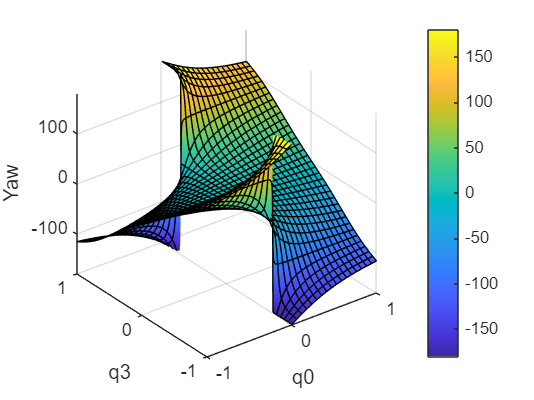

colorbar